# Direct Channel Estimation - Phase 1

**Based on the paper:** Channel Estimation for Intelligent Reflecting Surface Assisted Multiuser Communications: Framework, Algorithms, and Analysis 

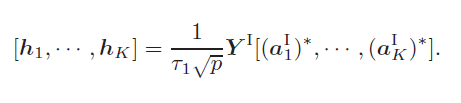 or

 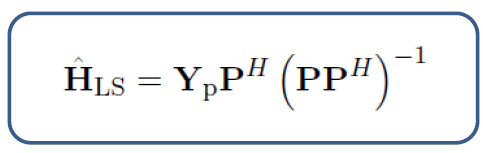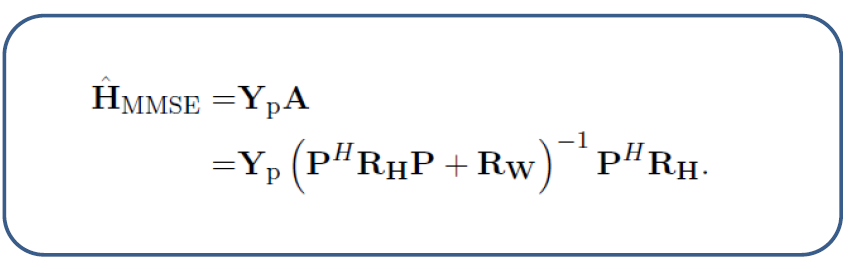

function [channel, MSE] = channelDirectEstimation2(sys, channel, estimation, wo_noise, pwr, P_extra, Y_extra)

    H = channel.H;
        
    noise_dbm = estimation.noise_dbm;
    T0 = estimation.T0_min;

    K = sys.n_tx;
    M = sys.n_rx;
    PWR = sys.PWR;

    % % Power Normalization -----------------------------------
    sigma2_n = (10^(noise_dbm/10));
    % sigma2_s = PWR(pwr);

    % Power Normalization -----------------------------------
    sigma2_nest = sigma2_n/(PWR(pwr));
    % sigma2_nest_extra = sigma2_n/(PWR(pwr)*idd.R);
    sigma2_s = 1;

    %% ===============Phase I===========================
    F0_temp=dftmtx(T0);
    pilots = F0_temp(1:K,:);
    pilots_extra = [pilots P_extra]*sqrt(sigma2_s); % pilots
    pilots_extra_H = pilots_extra';
   
    noise = sqrt(sigma2_nest/2)*(randn(M,T0)+1j*randn(M,T0));
    Y0 = H*pilots+noise;
    Y0_refined = [Y0 Y_extra];

    T0_aux = T0+size(P_extra,2);
    if wo_noise
        %% With noise --------------------------------------
        A = inv(pilots_extra_H*diag(channel.Hkloss)*pilots_extra + sigma2_nest*eye(T0_aux))*pilots_extra_H*diag(channel.Hkloss);
        H_est = Y0_refined*A;
   
    else
        %% Without noise -----------------------------------
        % pilots = abs(pilots);
        % pilotsH = abs(pilotsH);
        % Y0 = H*pilots+noise;
        factor = 1/(T0*sqrt(sigma2_s));
        H_est = factor*Y0_refined*pilots_extra_H*inv(pilots_extra*pilots_extra_H);
    end

    channel.H_est = H_est;
    modH2 = H(:)'*H(:);
    MSE=(H_est(:)-H(:))'*(H_est(:)-H(:))/modH2;
end
